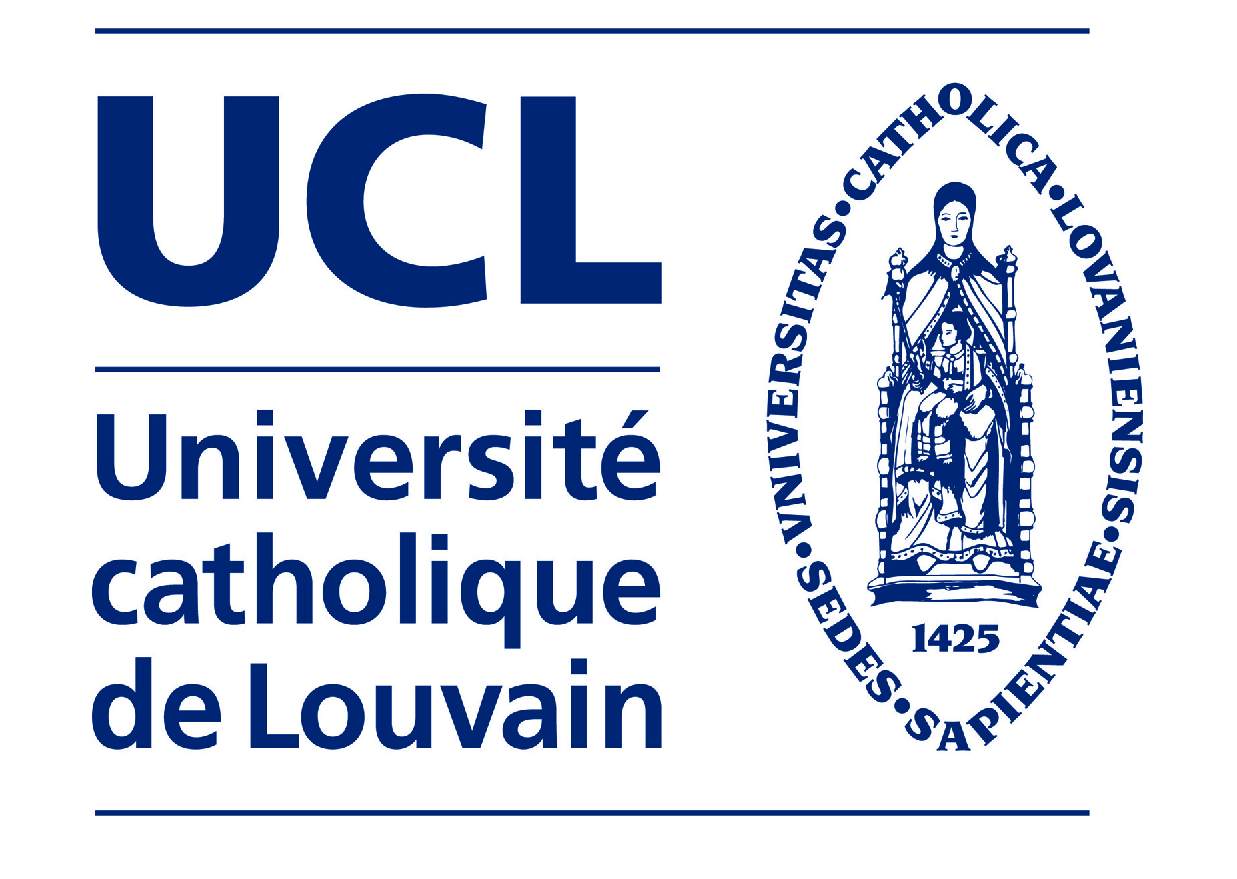

UCL = imread('MorphologyTests/logo_Ucl.png');
imshow(UCL);

level = graythresh(UCL)

level = 0.6000

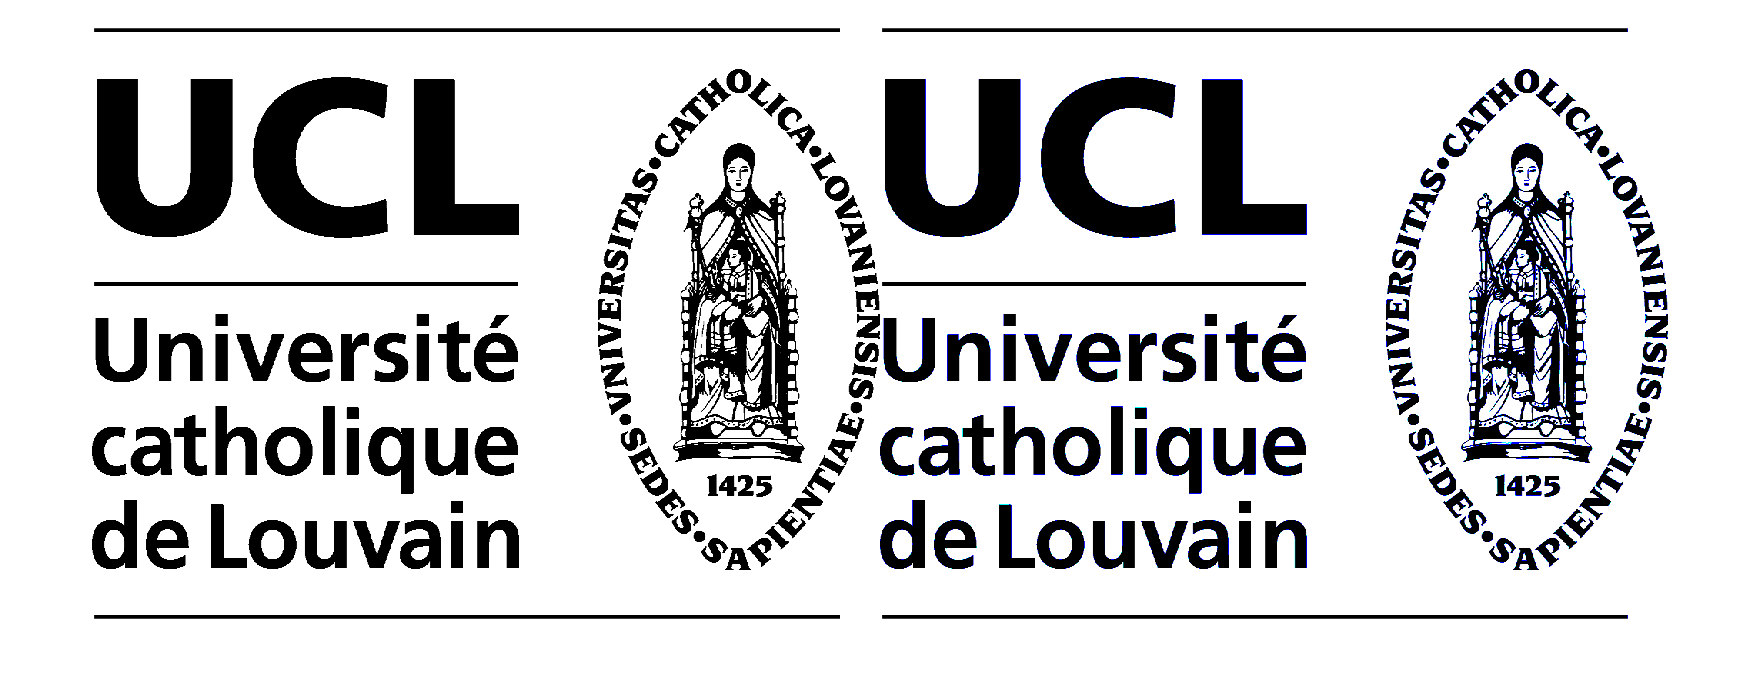

UCL_BINARY = imbinarize(UCL,level);
UCL_REDUX = UCL_BINARY(:, :, 1);
UCL_INVERTED = ~ UCL_REDUX;
imshowpair(UCL_REDUX,UCL_BINARY,'montage')

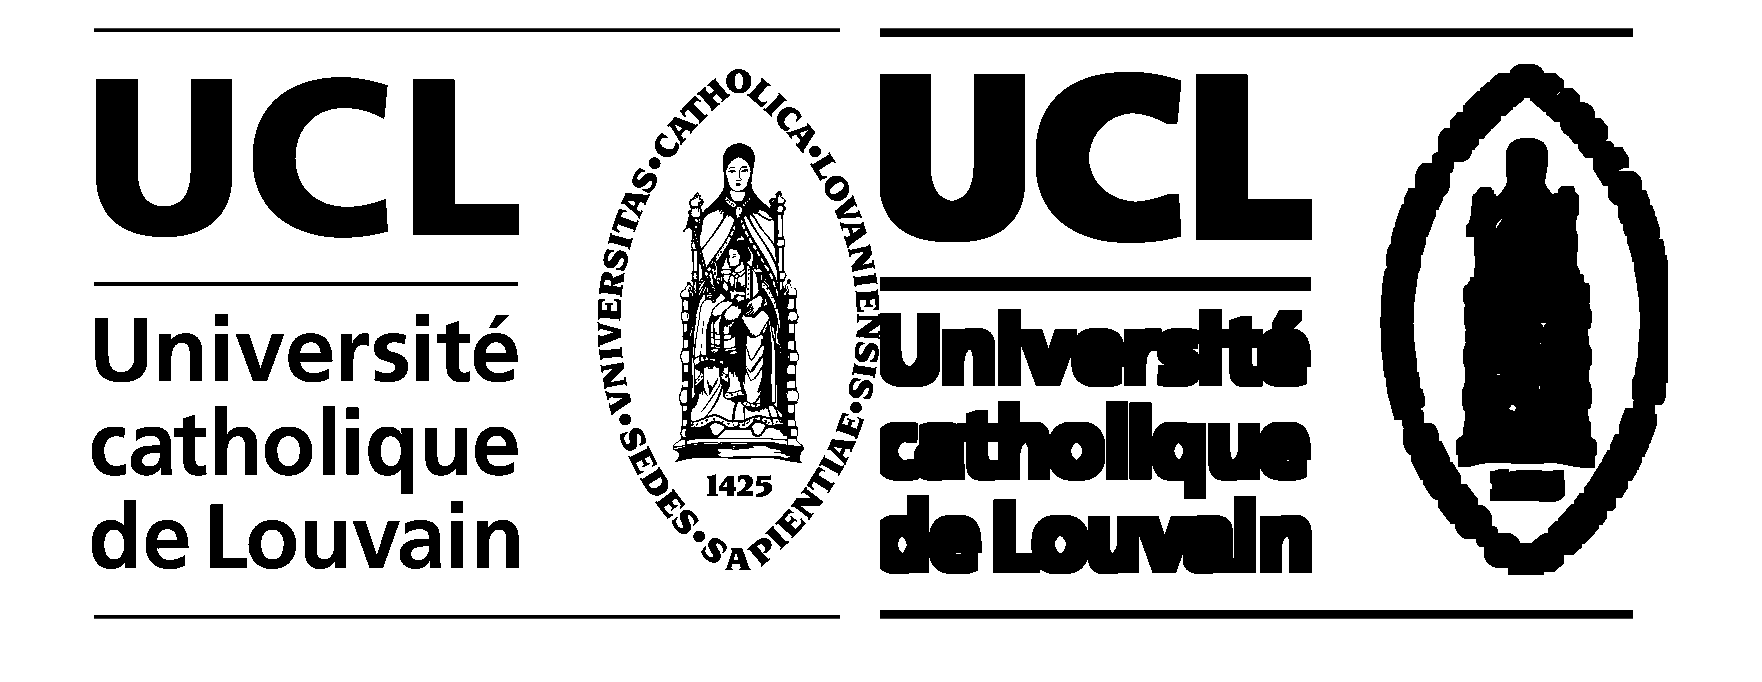

se = strel('square', 21);
eroded_brow = imerode(UCL_REDUX, se, 1 );
imshowpair(UCL_REDUX,eroded_brow,'montage')

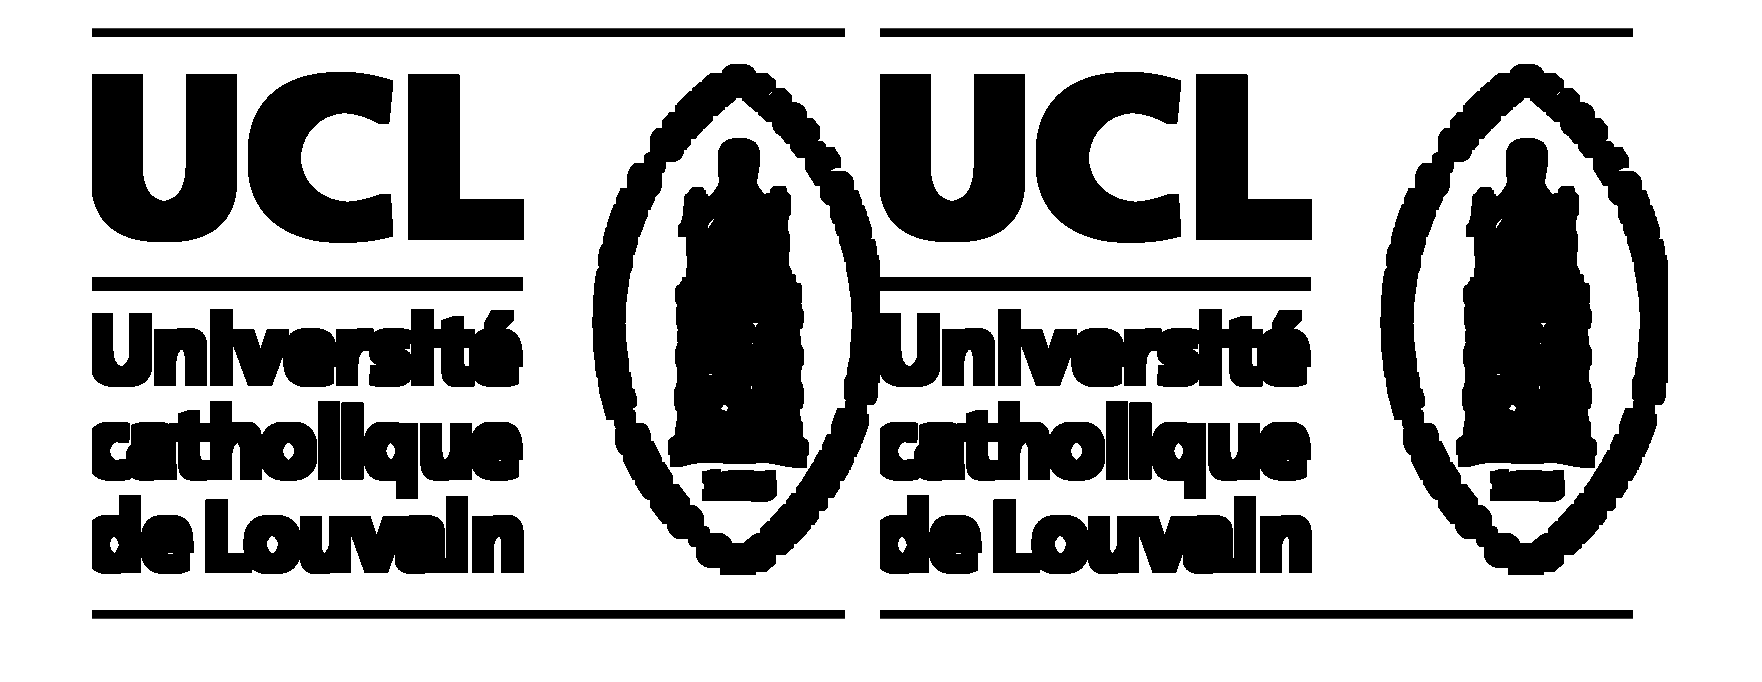

dilatated_brok = imdilate(UCL_INVERTED, se, 1);
imshowpair(~dilatated_brok,eroded_brow,'montage')

isequal(~dilatated_brok, eroded_brow)

ans = logical
   1
